# Improved Hough transform

Implementing the gradient-weighted Hough transform (GWHT), with potential improvements and refinements.

## Load image

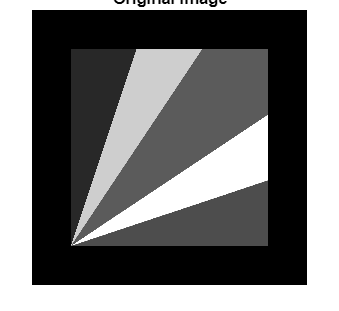

I = imread('testImage.png');
I = im2gray(I);
I = double(rescale(I));
figure()
imshow(I); title('Original image')

## Image preparation

### Add some blur and noise

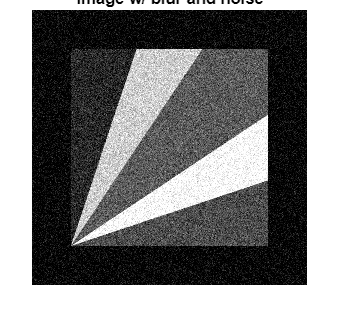

rng(123579); % Set fixed seed
Igauss = imgaussfilt(I,sqrt(2), 'FilterSize',5);
Inoise = imnoise(Igauss);
imshow(Inoise); title('Image w/ blur and noise')

### Calculating gradients

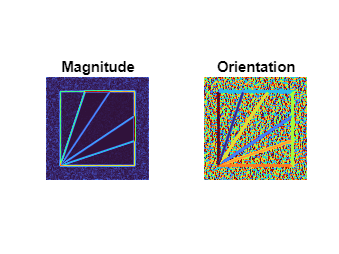

% Magnitude and direction
[Gxa, Gya] = gradientByRatio_v2(Inoise, 20);
Imagnitude = hypot(Gxa,Gya);
Iorientation = rad2deg(atan2(Gya,Gxa));

figure(); tiledlayout(1,2);
nexttile
imagesc(Imagnitude); colormap turbo; axis image; axis off; title('Magnitude')
nexttile
imagesc(Iorientation); colormap turbo; axis image; axis off; title('Orientation')

## Thresholding

% Thresholding
imScaledGradient = rescale(Imagnitude);
% otsuLevel = graythresh(imScaledGradient);
otsuLevels = multithresh(imScaledGradient,2)

otsuLevels =     0.1176    0.3765


imOtsu = imbinarize(imScaledGradient,otsuLevels(1));

Compare otsu levels

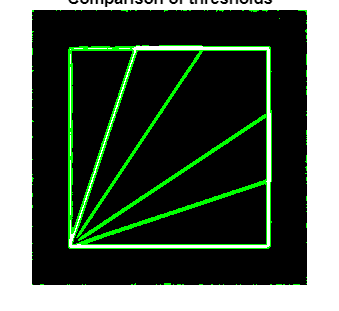

figure();imshowpair(imbinarize(imScaledGradient,otsuLevels(1)), ...
    imbinarize(imScaledGradient,otsuLevels(2))); title('Comparison of thresholds')

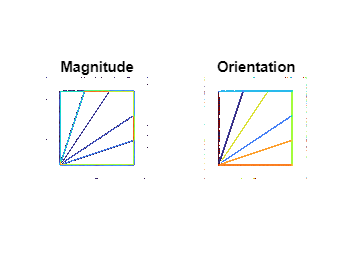

% threshVal = log(1.5276);
% imThreshold = Imagnitude>otsuLevel;

% Region reduction
CC = bwconncomp(imOtsu);
regionSizes = cellfun(@length,CC.PixelIdxList);
largeEnoughIdx = find(regionSizes>100);
p = regionprops(CC,"Area");
[~,maxIdx] = maxk([p.Area],2);
BW2 = cc2bw(CC,"ObjectsToKeep",maxIdx);

% Masks
mask = imOtsu;
maskedOrientation   = immultiply(Iorientation,mask); % Take only the data from the thresholded image
maskedMagnitude     = immultiply(Imagnitude,mask);
maskedOrientation(maskedOrientation==0) =NaN;
maskedMagnitude(maskedMagnitude==0)     =NaN;

figure(); tiledlayout(1,2); title('Masked')
nexttile
h1 = imagesc(maskedMagnitude); colormap turbo; axis image; axis off; title('Magnitude')
set(h1, 'AlphaData', ~isnan(maskedMagnitude))
nexttile
h2 = imagesc(maskedOrientation); colormap turbo; axis image; axis off; title('Orientation')
set(h2, 'AlphaData', ~isnan(maskedOrientation))

## Hough transform

sHough = GWHT(maskedOrientation,maskedMagnitude);

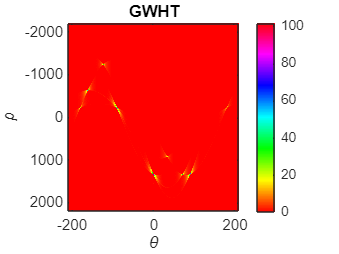

figure();
imagesc(sHough.hough, 'XData',sHough.theta, 'YData',sHough.rho);
colormap hsv; colorbar
xlabel('\theta'); ylabel('\rho'); 
title('GWHT')

## Extend Hough space

Hough space is now inherently extended to [-210,210] degrees within [GWHT.m](matlab:open('./GWHT.m')).

Peak relocating and clustering will happen after peaks are found.

## Finding peaks

rhoSpace = sHough.rho;
numPeaks = 100;
integerHough = round(sHough.hough.*100); %Multiplication to improve accuracy of rounding
peaks = houghpeaks(integerHough, ...
    numPeaks, ...
    "Threshold", ceil(0.1*max(integerHough(:))));%,...
    % "NHoodSize", [51,51]);


So a suppression neighbourhood isn't necessarily the best thing, since it means that "peaks" on the edges of the cut out zone will be considered (when they're not really peaks)

Instead, I could develop/implement some peak-climbing algorithm

## Peak optimisation

The goal here is to find initially many peaks, and then cut them down to the significant ones.

Find the magnitude of each peak

linearIdx = sub2ind(size(sHough.hough), peaks(:,1), peaks(:,2));
values = sHough.hough(linearIdx)

values =   101.5476
   89.6736
   85.1322
   54.2927
   39.8065
   39.6900
   39.2709
   35.2677
   31.9523
   31.8287


peaks(:,3) = values;
% Sort peaks in ascending theta order
peaks = sortrows(peaks,2)

peaks = 1.0e+03 *

    2.0320    0.1380    0.0107
    1.9860    0.1510    0.0318
    1.9400    0.1630    0.0108
    1.6230    0.2290    0.0174
    1.5770    0.2430    0.0543
    1.5310    0.2580    0.0190
    0.9740    0.4330    0.0353
    1.8940    0.5780    0.0158
    1.9400    0.5870    0.0310
    1.9860    0.6010    0.0897


***peaks***** is [rho, theta, magnitude]**

## Plotting peaks

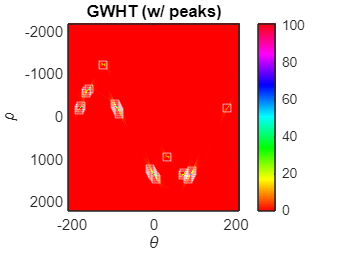

figure();
imagesc(sHough.hough, 'XData',sHough.theta, 'YData',sHough.rho);
colormap hsv; colorbar
xlabel('\theta'); ylabel('\rho'); 
title('GWHT (w/ peaks)')
x = sHough.theta(peaks(:,2)); y = sHough.rho(peaks(:,1));
hold on
plot(x,y,'s','color','white');
hold off

*WORK IN PROGRESS*

## Peak clustering

Using DBSCAN to associate detected peaks which belong to the same true peak together.

Due to the extended theta domain, some peaks may be doubled. These should be clustered separately, and then have clusters matched together.

Consider a weighted averaging to find the "true" peak.

Set minpts = 1, because a single detection is also valid.

How do we determine epsilon? Tricky. But we can use the mahalanobis distance!

eps = 50; % Initial test
minPts = 1;
clusterLabel = dbscan(peaks, eps, minPts,"Distance","mahalanobis");
clustColours = hsv(length(unique(clusterLabel)));
colourlist = zeros([height(peaks) 3]);
for i=1:length(colourlist)
    if clusterLabel(i) ~= -1
        colourlist(i,:) = clustColours(clusterLabel(i),:);
    else % Specific colour for ungrouped bozos
        colourlist(i,:) = [0,0,0];
    end
end
length(unique(clusterLabel))

ans = 9

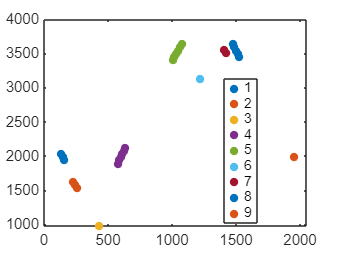

figure();
gscatter(peaks(:,2), peaks(:,1), clusterLabel)

Initial test has actually worked perfectly.

## Associate clusters

Thanks to the expanded Hough domain, paired clusters will be 360° apart

% Find theta resolution, and rho resolution (for later)
thetaRes = sHough.theta(2)-sHough.theta(1);
rhoRes = sHough.rho(2)-sHough.rho(1);
% Find how many theta vals later that corresponds to
indexDiff = 360/thetaRes;

We only need to look at the first 60 degrees

% Similarly calculated
stopIdx = (60/thetaRes)+1; % The index at which to stop checking

Iterate through all, until 60° has passed.

% Initialise merging pairs list
mergingPairs = [];
for i=2%1:height(sortedpeaks)
    if peaks(i,2)<stopIdx
        corrTheta = round(peaks(i,2) + indexDiff); % This has to be an integer
        corrPoint = [peaks(i,1), corrTheta];

        % Check if this exists
        idx = find(ismember(peaks(:,1:2), corrPoint, "rows"));
        if ~isempty(idx)
            % Correlate these points
            mergingPairs = [mergingPairs; clusterLabel(i), clusterLabel(idx)]
        end

    else
        break
    end
end

mergingPairs =      1     9


Correlate the clusters

% Make a graph
G = graph(mergingPairs(:,1), mergingPairs(:,2))

G =   graph with properties:

    Edges: [1×1 table]
    Nodes: [9×0 table]


% Find connected components
componentID = conncomp(G)

componentID =      1     2     3     4     5     6     7     8     1


% Initialise new label list
connClustLabel = zeros(size(clusterLabel));
% Now relabel points
for i=1:length(clusterLabel)
    oldLabel = clusterLabel(i);
    newLabel = componentID(oldLabel);
    connClustLabel(i)=newLabel;
end
connClustLabel

connClustLabel =      1
     1
     1
     2
     2
     2
     3
     4
     4
     4


## Finding average peak location

For each cluster, there must be a "true" peak location. We can take a weighted average.

*There will be an edge case for clusters that wrap around the boundaries. Computing circular averages must be considered - there's a circular statistics toolbox for MATLAB that could be good to look into.*

In the general case

% For each unique cluster
meanPeaks = [];
for i=1:length(unique(connClustLabel))
    % Slice all the peaks belonging to this cluster
    clusterPeaks = peaks(connClustLabel==i,:);
    
    % Some check here to see if the cluster is disparate
    %%% Since clusterPeaks is already sorted according to theta, check the
    %%% distance between first theta and last theta
    if clusterPeaks(end,2)-clusterPeaks(1,2) > 0.5*indexDiff
        % Threshold chosen to be larger than any legitimate nondisparate cluster, but
        % smaller than any legitimate disparate cluster
        disp('Disparity detected')
        % If disparate, add to the smaller values - any theta values less
        % than 0° get 360° added to them
        for j=1:height(clusterPeaks)
            if clusterPeaks(j,2) < 210/thetaRes
                clusterPeaks(j,2) = clusterPeaks(j,2) + 360/thetaRes;
            end
        end
    end

    % Calculate a weighted mean
    meanRho     = mean(clusterPeaks(:,1),'Weights',clusterPeaks(:,3));
    meanTheta   = mean(clusterPeaks(:,2),'Weights',clusterPeaks(:,3));

    meanPeaks = [meanPeaks; meanRho, meanTheta];
end

Disparity detected


Let's plot these peaks and see how well they work on this data.

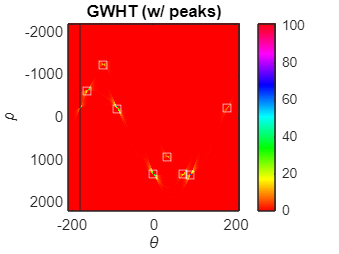

figure();
imagesc(sHough.hough, 'XData',sHough.theta, 'YData',sHough.rho);
colormap hsv; colorbar
xlabel('\theta'); ylabel('\rho'); 
title('GWHT (w/ peaks)')

x = min(sHough.theta) + meanPeaks(:,2)*thetaRes;
y = min(sHough.rho) + meanPeaks(:,1)*rhoRes;
% x = sHough.theta(peaks(:,2)); y = sHough.rho(peaks(:,1));
hold on
plot(x,y,'s','color','white');
hold off
xline(-180)

## Reconstruct lines

for j=1:length(meanPeaks)
    pk = round(meanPeaks(j,:));
    % Find a new mask for that peak. Within a range of the peak angle
    pkAngle = sHough.theta(pk(2));
    pkMask = zeros(size(mask));
    pkMask(maskedOrientation>(pkAngle-10) & maskedOrientation<(pkAngle+10)) = 1;
    pkLine = houghlines(pkMask, sHough.theta,rhoSpace,pk,...
        "FillGap",50, "MinLength", 100);

    if j==1 % For the first one, initialise the new big struct
        sLines = pkLine;
    else
        sLines = [sLines, pkLine];
    end
end

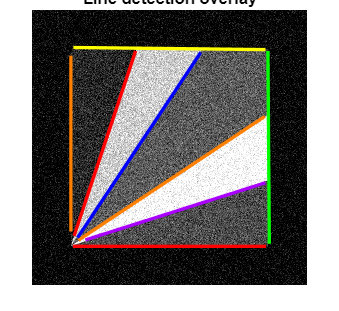

tLines = struct2table(sLines);
thetaRhoVals = [sLines.theta;sLines.rho]';
uniqueVals = unique(thetaRhoVals,"rows");
colours = prism(length(uniqueVals));

for i=1:length(uniqueVals) %for each unique value
    idx = and(any(thetaRhoVals == uniqueVals(i,1),2), ...
        any(thetaRhoVals == uniqueVals(i,2),2)); % Matching rows
    tLines.label(idx) = i;
end

figure, imshow(Inoise), hold on
for k = 1:height(tLines)
   xy = [tLines.point1(k,:); tLines.point2(k,:)];
   colour = colours(tLines.label(k),:);
   plot(xy(:,1),xy(:,2),'LineWidth',2,'Color',colour);
end
title('Line detection overlay');

hold off